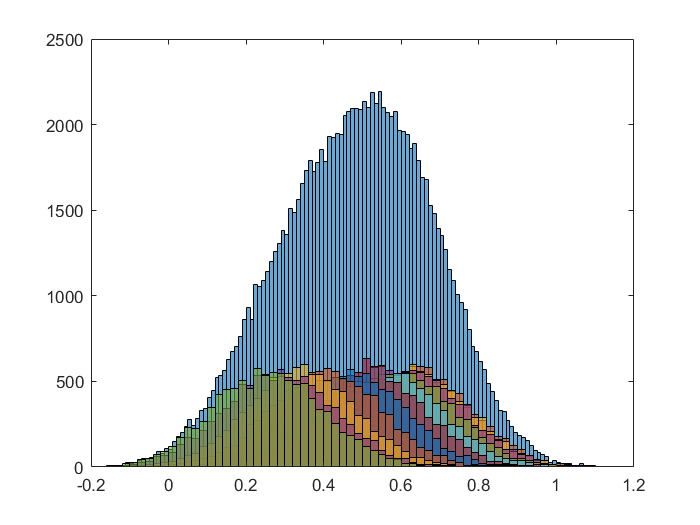

clear;
frequency = [4];
ks = 0; 
E_oil = 3;
E_air = 1;
temp = 20;
salinity = 35;
theta = 0;
variance = 0.02;
tmin = 0;
tmax = 10;
thickness_step = 1;
thickness = tmin:thickness_step:tmax;

R_oil = reflectivity(frequency, thickness, ks, E_oil, E_air, temp, salinity, theta);
noise = sqrt(variance) * randn(10000, length(R_oil));
noisy = R_oil + noise;

h = pdf("Normal", noisy, R_oil, sqrt(variance));

histogram(noisy)
hold on;
for i = 1:1:length(thickness)
    
    histogram(noisy(:, i));
    xlim([-0.2, 1.2])
    
end


% pO = 0.5;
% pW = 0.5;

% 
% 
% M = 5;
% t = tmin+(tmax-tmin)*rand(1,1);
% t = 2;
% 
% reflectivities = reflectivity(frequency, t, ks, E_oil, E_air, temp, salinity, theta);
% noise = sqrt(variance) * randn(M, length(frequency));
% noisy_reflectivities = transpose(reflectivities) + noise;           % M x K matrix, K : number of frequencies, M : number of observations
% 
% for i = 1:1:1000
%     x(i) = Detect_with_unknown_thickness(noisy_reflectivities, M, frequency, ks, variance, E_oil, E_air, temp, salinity, theta, tmin, thickness_step, tmax);
% end   
% 
% sum(x<=1)
% 
% 